# **CS 5487 Programming Assignment 2 part1**

## **(a) Implementation of 3 algorithms can be found in the seperated function matlab files**

- K-means algorithm kmeans.m

- EM algorithm for Gaussian mixture models (EM-GMM) emgmm.m

- Mean-shift algorithm ms.m

- initialize the parameters for EM for gaussian mixture model init_parameter.m

- Calculate the n*k matrix of multivariate gaussian result multiGaussian.m

load("../PA2-cluster-data/cluster_data.mat");

## (b) Run the three algorithms on the three dataset and compare the results

- K-means

- EM algorithm for Gaussian mixture models (EM-GMM)

- Mean-shift algorithm

num_component = 4;
globalStream = RandStream('mlfg6331_64','NormalTransform','Polar');

%Data_A
%kmeans
[z_kmeans_a, mu_keams_a] = kmeans(num_component, dataA_X, inf, 50);
[z_kmeans_b, mu_keams_b] = kmeans(num_component, dataB_X, inf, 50);
[z_kmeans_c, mu_keams_c] = kmeans(num_component, dataC_X, inf, 50);


%emgmm
round = 100;
[z_emgmm_a, N_emgmm_a, pi_emgmm_a, mu_emgmm_a, sigma_emgmm_a] = emgmm(dataA_X, num_component, inf, 50);
[z_emgmm_b, N_emgmm_b, pi_emgmm_b, mu_emgmm_b, sigma_emgmm_b] = emgmm(dataB_X, num_component, inf, 50);
[z_emgmm_c, N_emgmm_c, pi_emgmm_c, mu_emgmm_c, sigma_emgmm_c] = emgmm(dataC_X, num_component, inf, 50);

%mean-shift
h = 3;
[mu_ms_a, z_ms_a] = ms(dataA_X, h, inf);
h = 2.4;
[mu_ms_b, z_ms_b] = ms(dataB_X, h, inf);
h = 3;
[mu_ms_c, z_ms_c] = ms(dataC_X, h, inf);

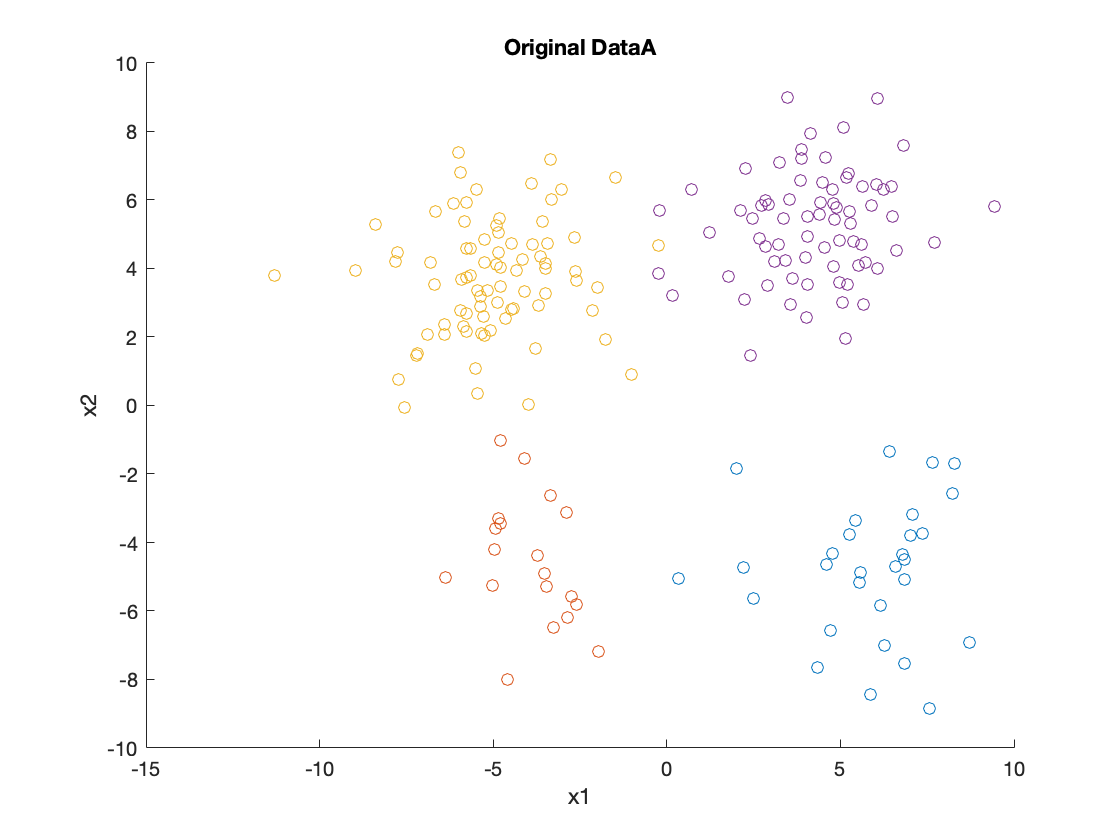


%plot the original data
for i = 1:size(dataA_X, 2)
    temp = dataA_X(:, dataA_Y==i);
    scatter(temp(1,:), temp(2,:));
    hold on
end
hold off
xlabel("x1");
ylabel("x2");
title("Original DataA");

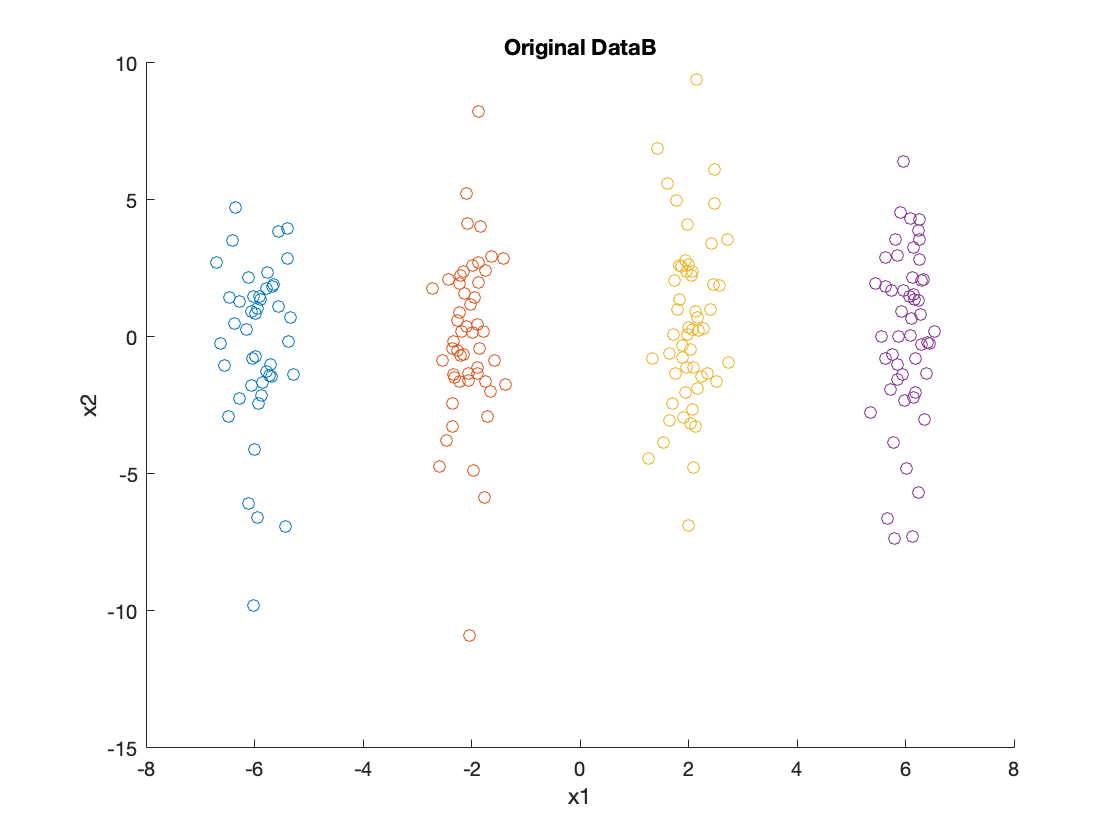


for i = 1:size(dataB_X, 2)
    temp = dataB_X(:, dataB_Y==i);
    scatter(temp(1,:), temp(2,:));
    hold on
end
hold off
xlabel("x1");
ylabel("x2");
title("Original DataB");

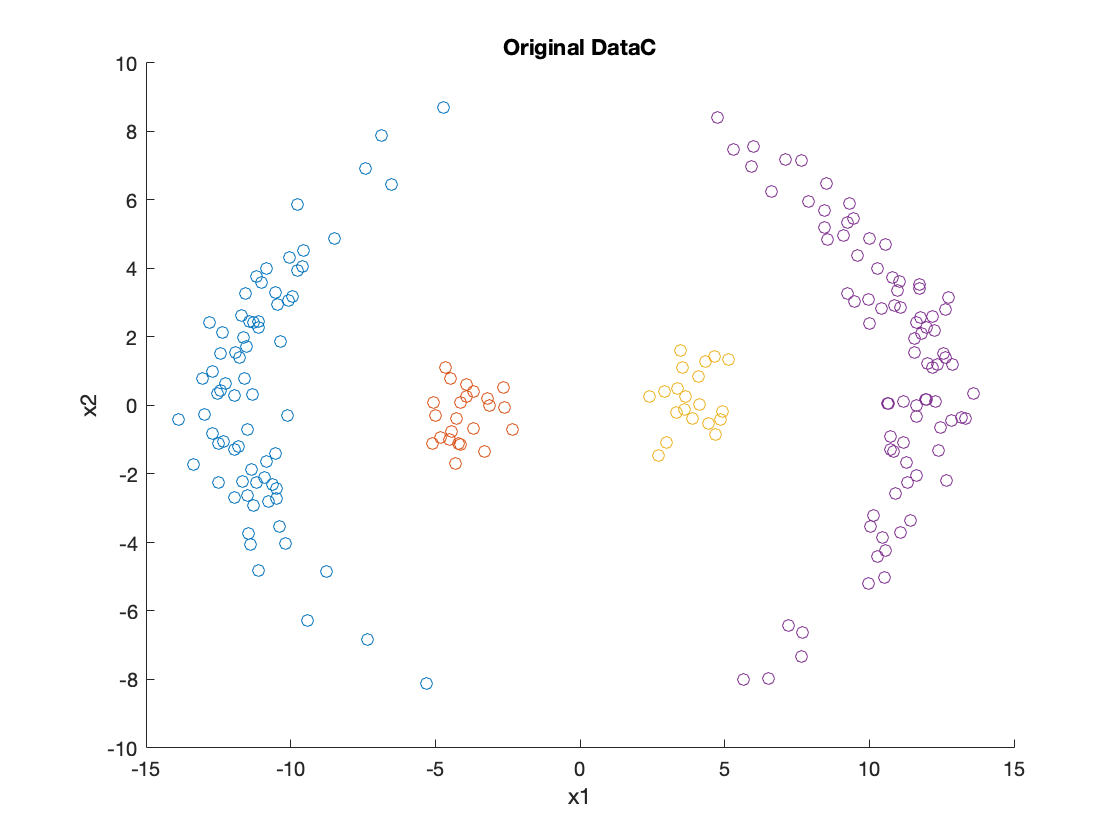


for i = 1:size(dataC_X, 2)
    temp = dataC_X(:, dataC_Y==i);
    scatter(temp(1,:), temp(2,:));
    hold on
end
hold off
xlabel("x1");
ylabel("x2");
title("Original DataC");

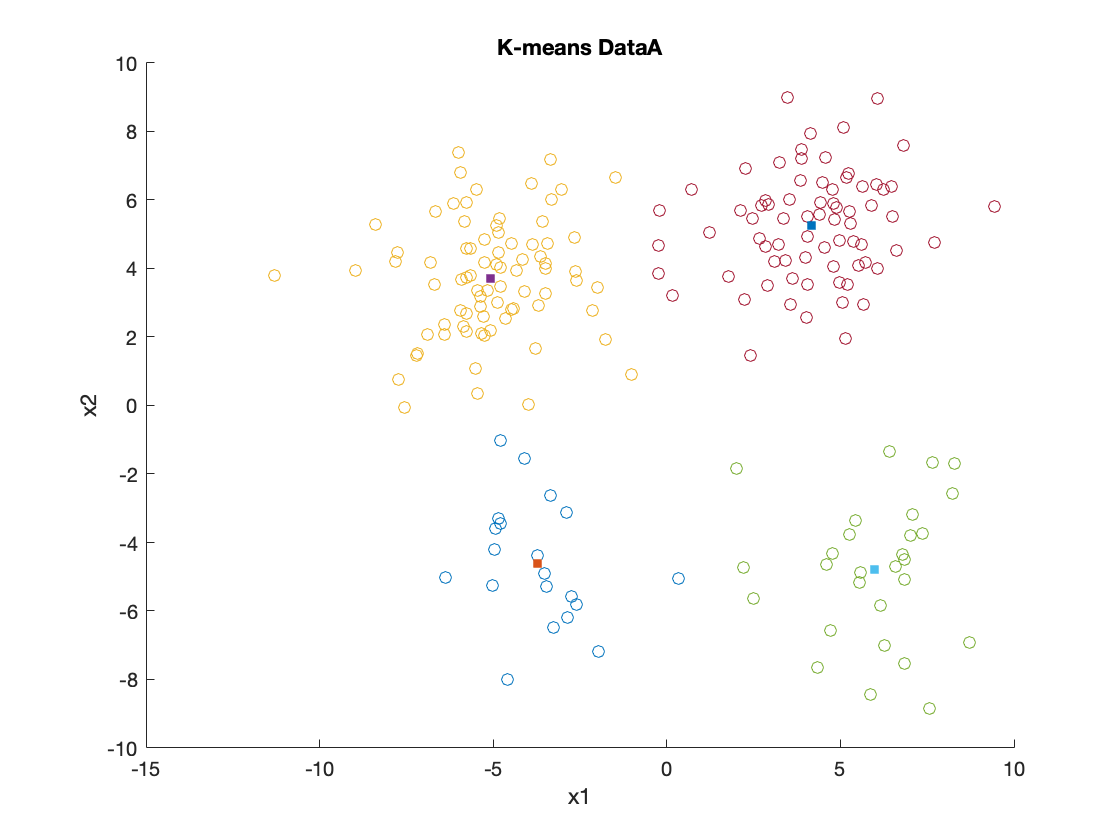


%K-means Data A,B,C
%A
for i = 1:num_component
    temp = z_kmeans_a';
    temp = dataA_X(:, temp(i,:)==1);
    scatter(temp(1,:), temp(2,:));
    hold on
    scatter(mu_keams_a(1,i), mu_keams_a(2,i), 30, "filled", "s");
end
hold off
xlabel("x1");
ylabel("x2");
title("K-means DataA");

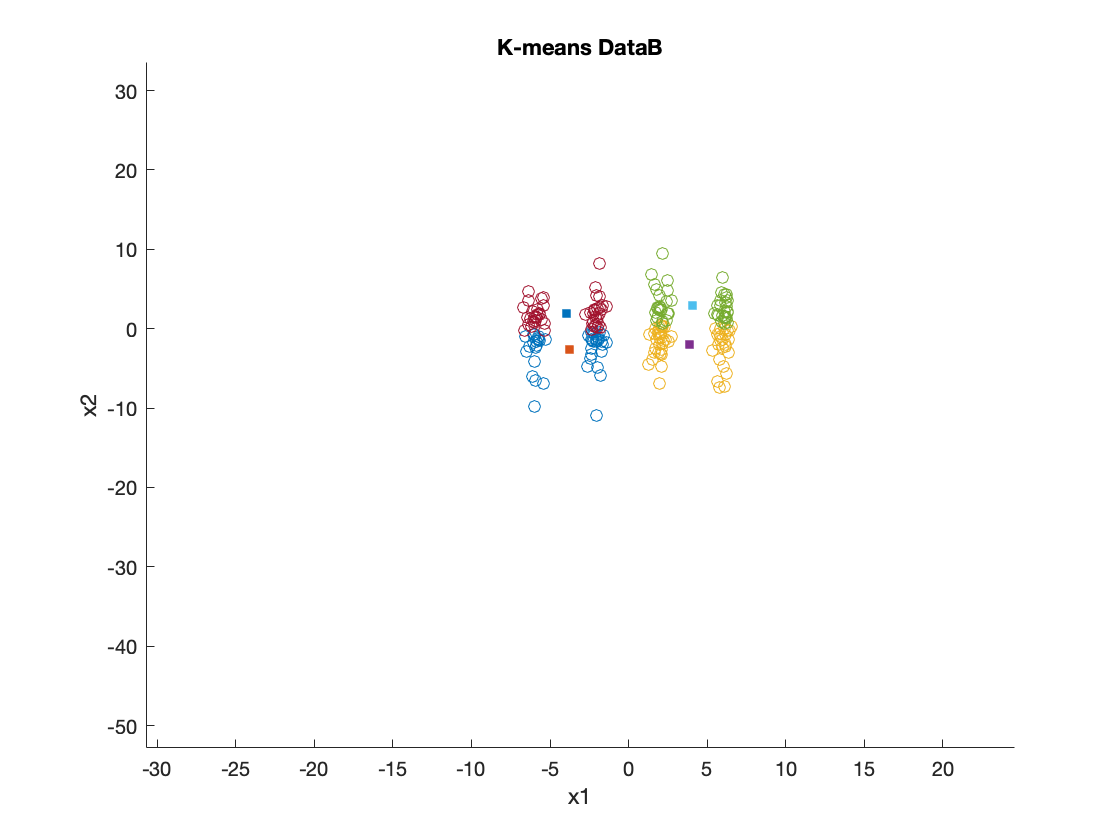

%B
for i = 1:num_component
    temp = z_kmeans_b';
    temp = dataB_X(:, temp(i,:)==1);
    scatter(temp(1,:), temp(2,:));
    hold on
    scatter(mu_keams_b(1,i), mu_keams_b(2,i), 30, "filled", "s");
end
hold off
xlabel("x1");
ylabel("x2");
title("K-means DataB");

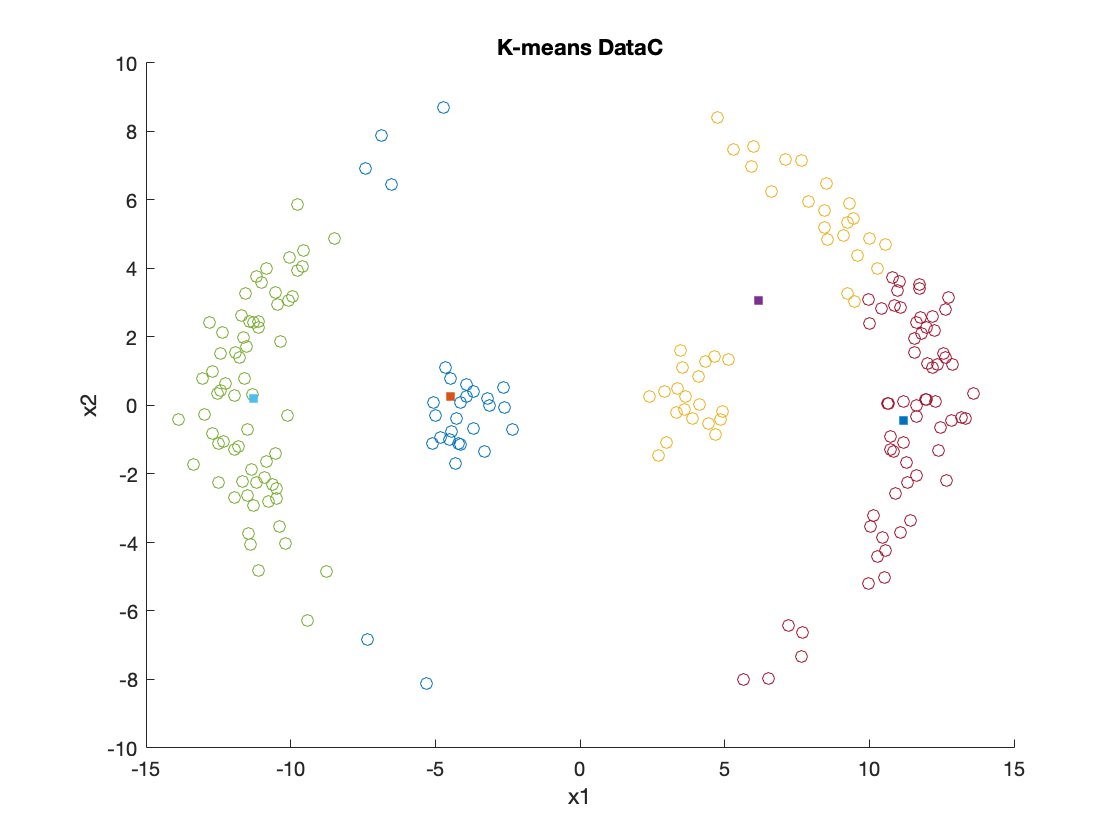

%C
for i = 1:num_component
    temp = z_kmeans_c';
    temp = dataC_X(:, temp(i,:)==1);
    scatter(temp(1,:), temp(2,:));
    hold on
    scatter(mu_keams_c(1,i), mu_keams_c(2,i), 30, "filled", "s");
end
hold off
xlabel("x1");
ylabel("x2");
title("K-means DataC");

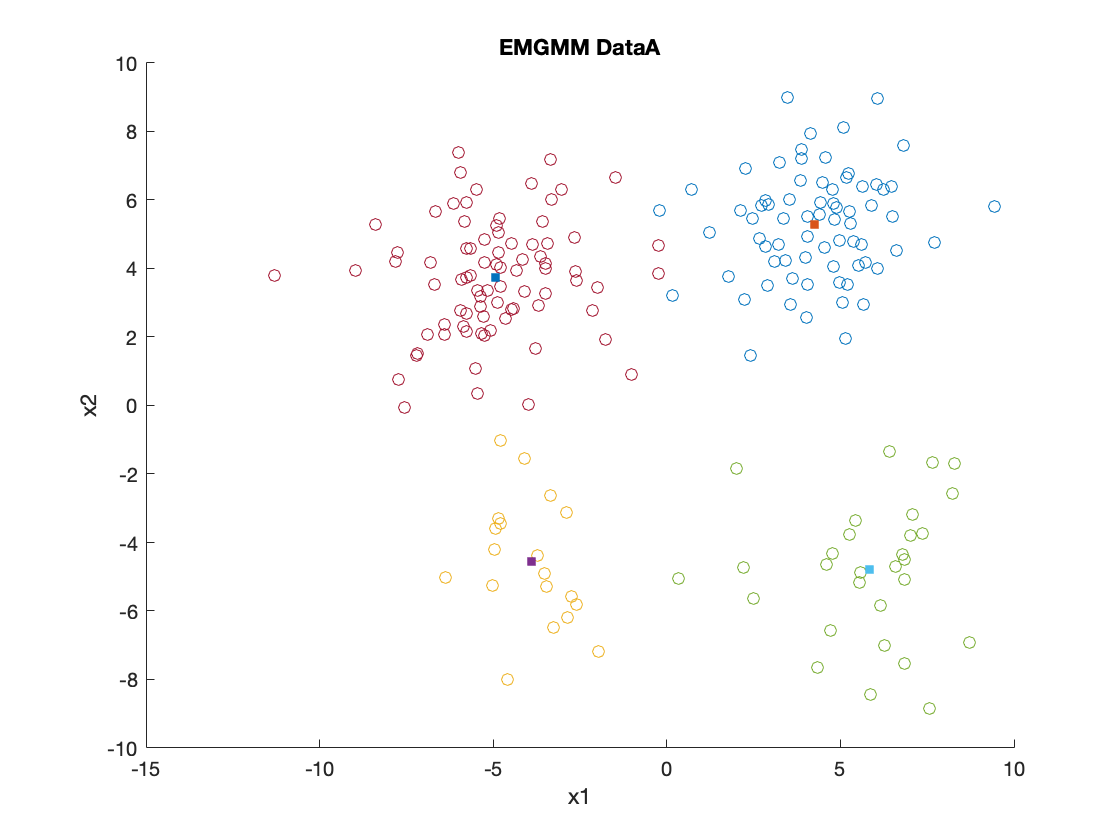

%EMGMM
%A
for i = 1:num_component
    temp = z_emgmm_a';
    [~,temp_idx] = max(temp); 
    temp = dataA_X(:, temp_idx==i);
    scatter(temp(1,:), temp(2,:));
    hold on
    scatter(mu_emgmm_a(1,i), mu_emgmm_a(2,i), 30, "filled", "s");
end
hold off
xlabel("x1");
ylabel("x2");
title("EMGMM DataA");

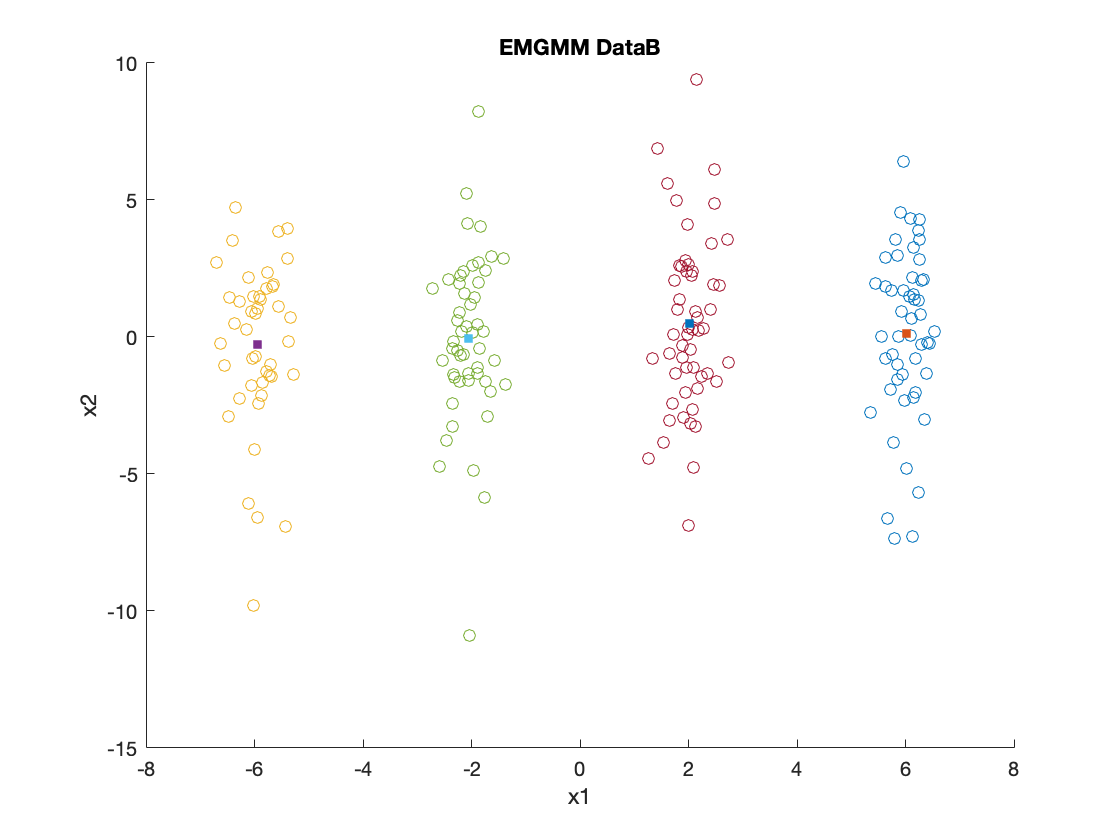


%B
for i = 1:num_component
    temp = z_emgmm_b';
    [~,temp_idx] = max(temp); 
    temp = dataB_X(:, temp_idx==i);
    scatter(temp(1,:), temp(2,:));
    hold on
    scatter(mu_emgmm_b(1,i), mu_emgmm_b(2,i), 30, "filled", "s");
end
hold off
xlabel("x1");
ylabel("x2");
title("EMGMM DataB");

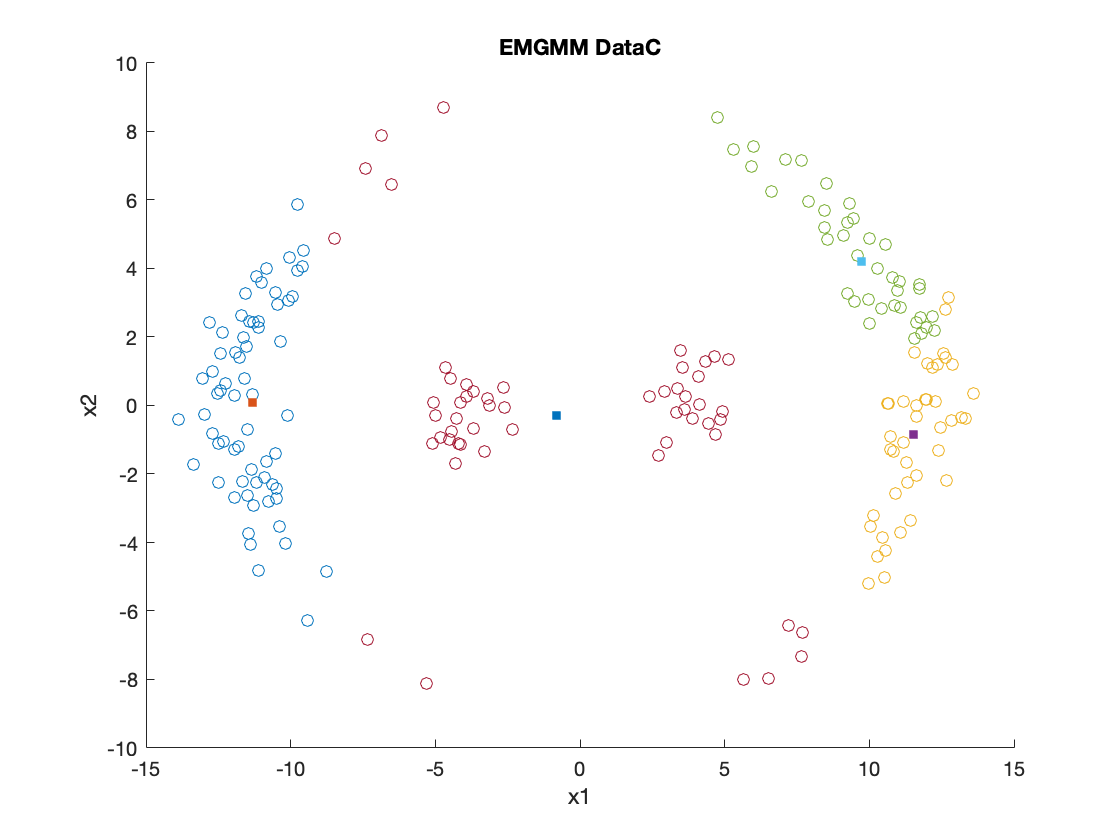


%C
for i = 1:num_component
    temp = z_emgmm_c';
    [~,temp_idx] = max(temp); 
    temp = dataC_X(:, temp_idx==i);
    scatter(temp(1,:), temp(2,:));
    hold on
    scatter(mu_emgmm_c(1,i), mu_emgmm_c(2,i), 30, "filled", "s");
end
hold off
xlabel("x1");
ylabel("x2");
title("EMGMM DataC");

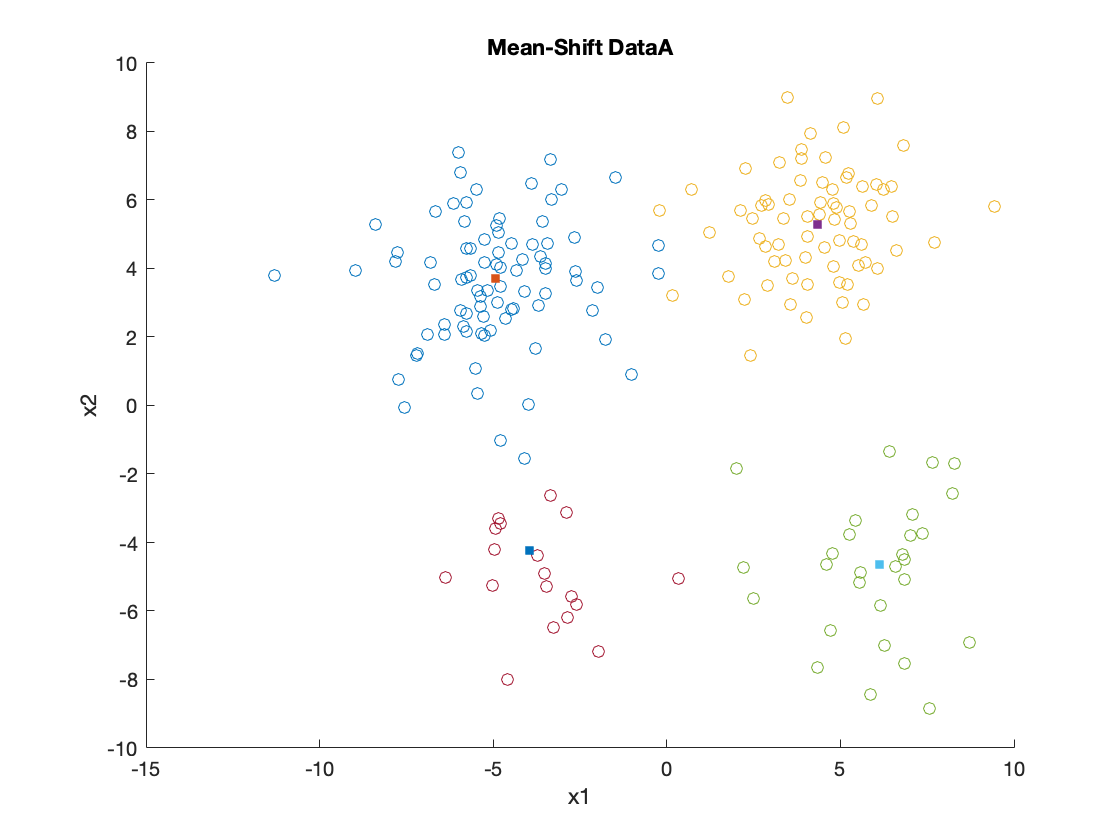

%Mean-shift
%A
num_component = size(mu_ms_a, 2);
for i = 1:num_component
    temp = dataA_X(:, z_ms_a==i);
    scatter(temp(1,:), temp(2,:));
    hold on
    scatter(mu_ms_a(1,i), mu_ms_a(2,i), 30, "filled", "s");
end
hold off
xlabel("x1");
ylabel("x2");

title("Mean-Shift DataA");

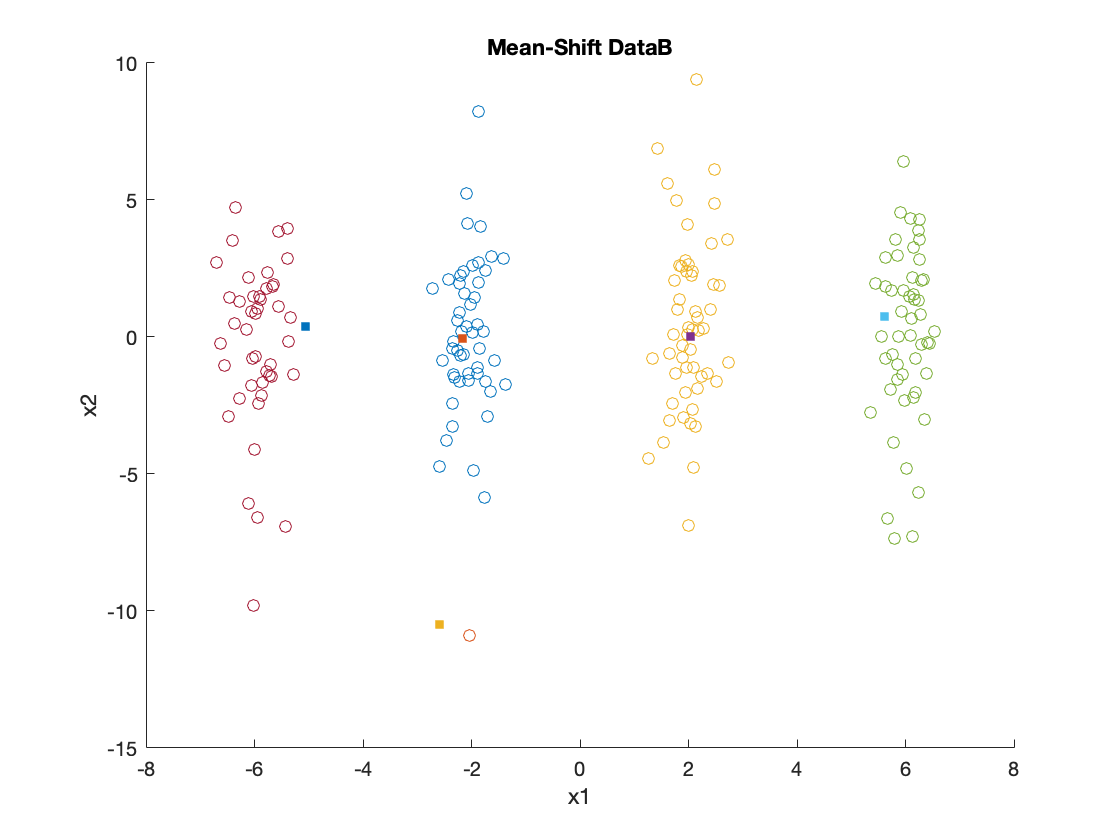


%B
num_component = size(mu_ms_b, 2);
for i = 1:num_component
    temp = dataB_X(:, z_ms_b==i);
    scatter(temp(1,:), temp(2,:));
    hold on
    scatter(mu_ms_b(1,i), mu_ms_b(2,i), 30, "filled", "s");
end
hold off
xlabel("x1");
ylabel("x2");

title("Mean-Shift DataB");

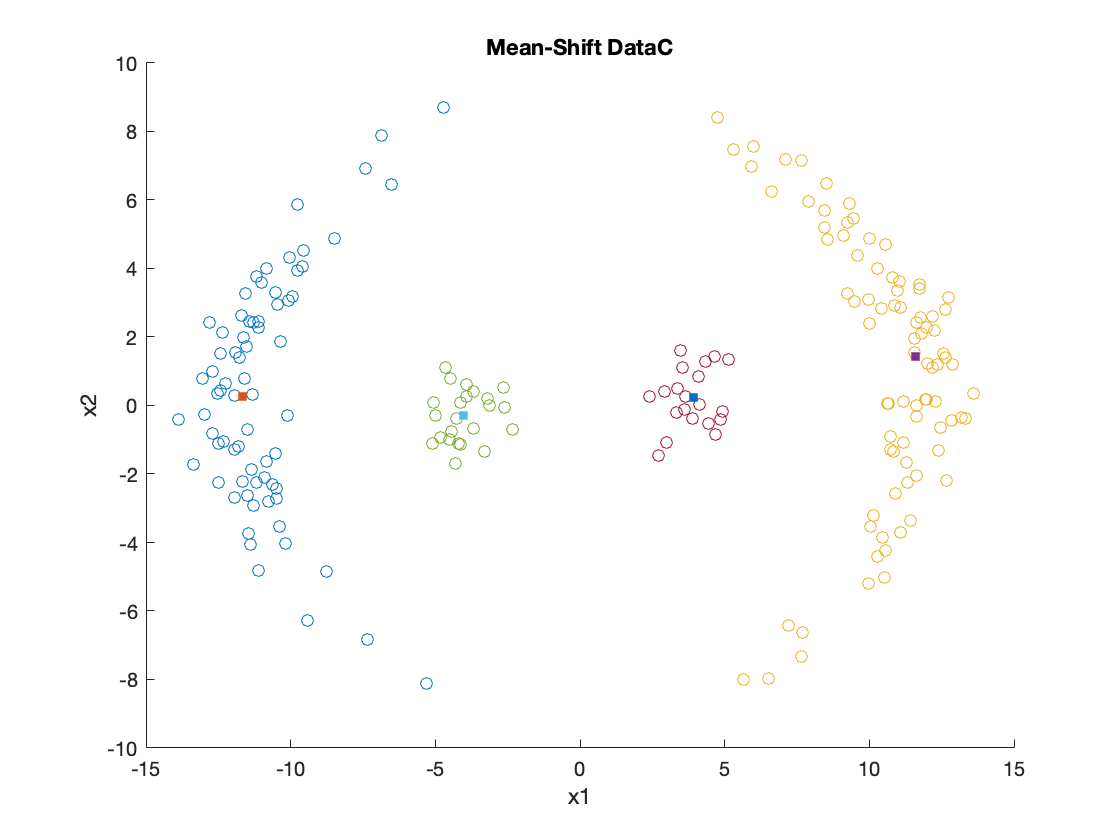


%C
num_component = size(mu_ms_c, 2);
for i = 1:num_component
    temp = dataC_X(:, z_ms_c==i);
    scatter(temp(1,:), temp(2,:));
    hold on
    scatter(mu_ms_c(1,i), mu_ms_c(2,i), 30, "filled", "s");
end
hold off
xlabel("x1");
ylabel("x2");

title("Mean-Shift DataC");

## (c) Sensitivity of bandwidth h

In this section, we will select different bandwidth h for the mean shift algorithm and compare their performance.

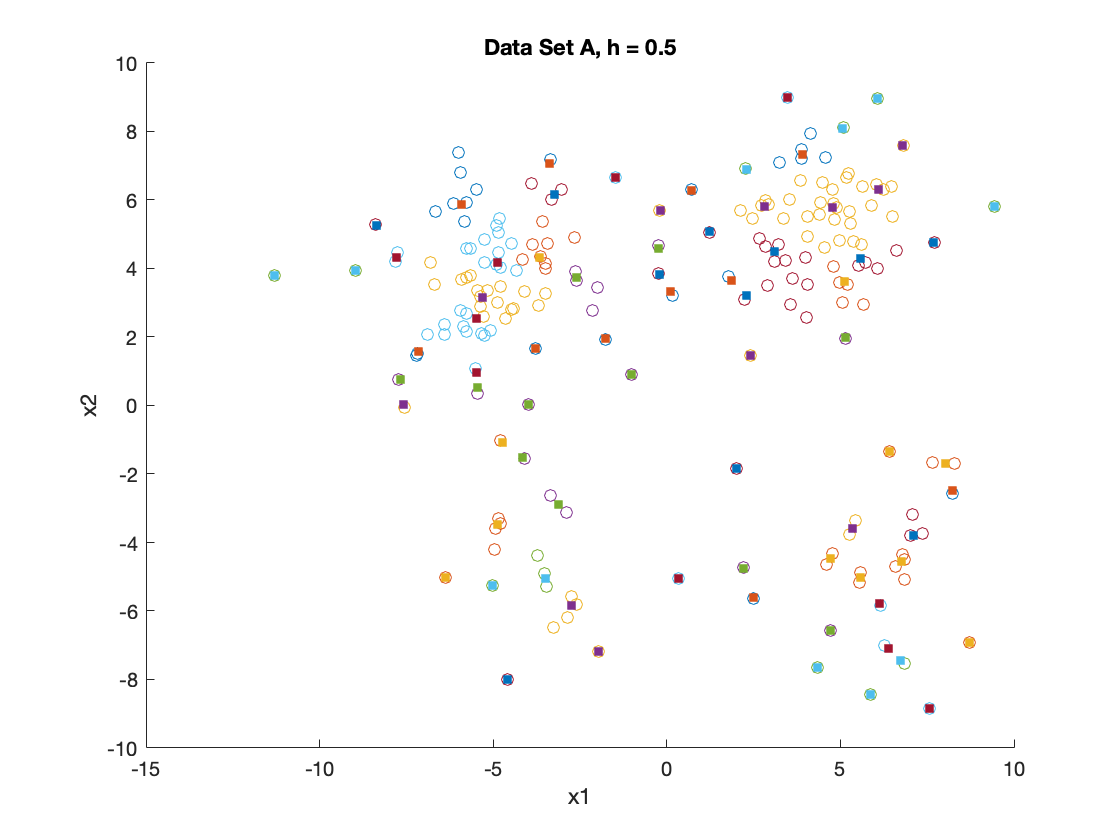

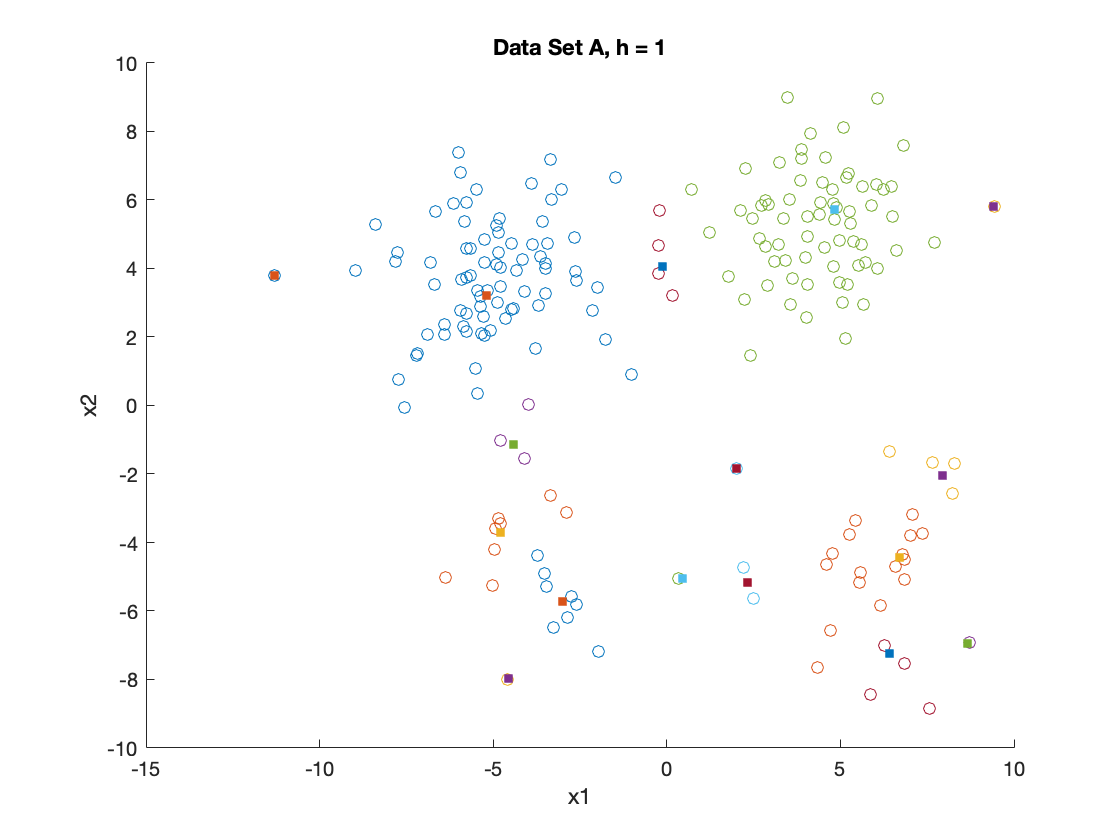

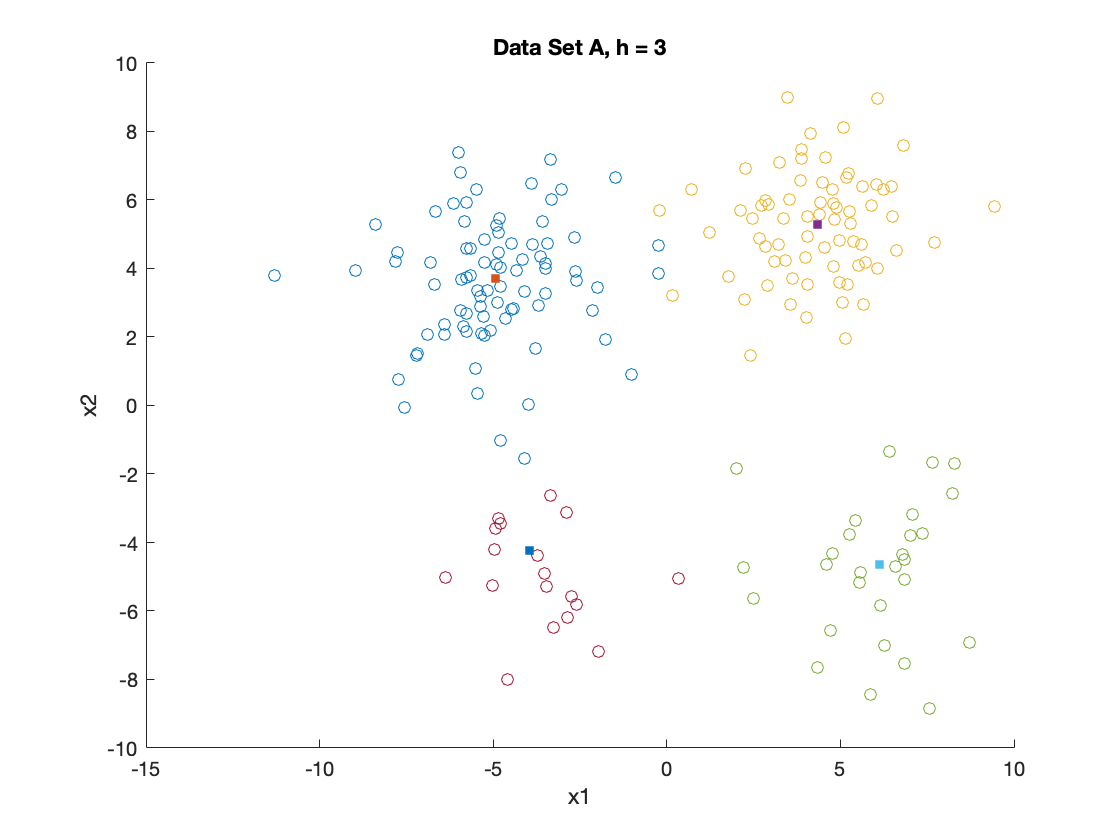

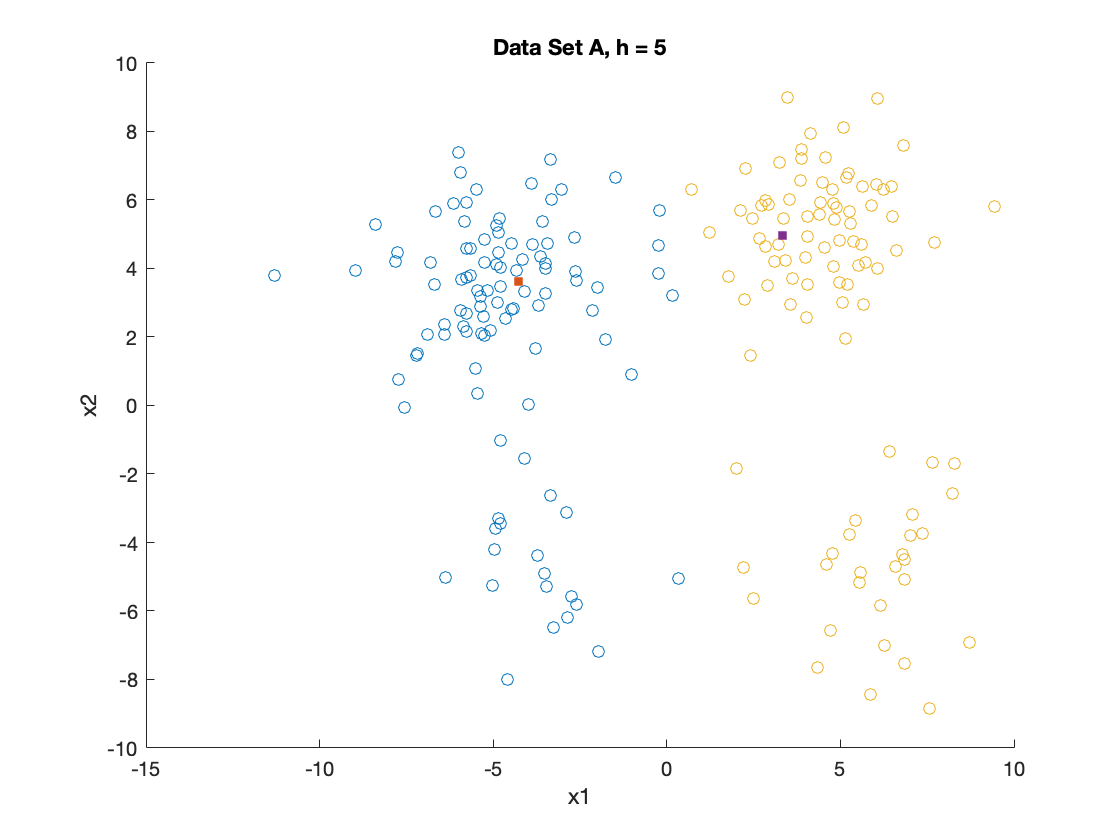

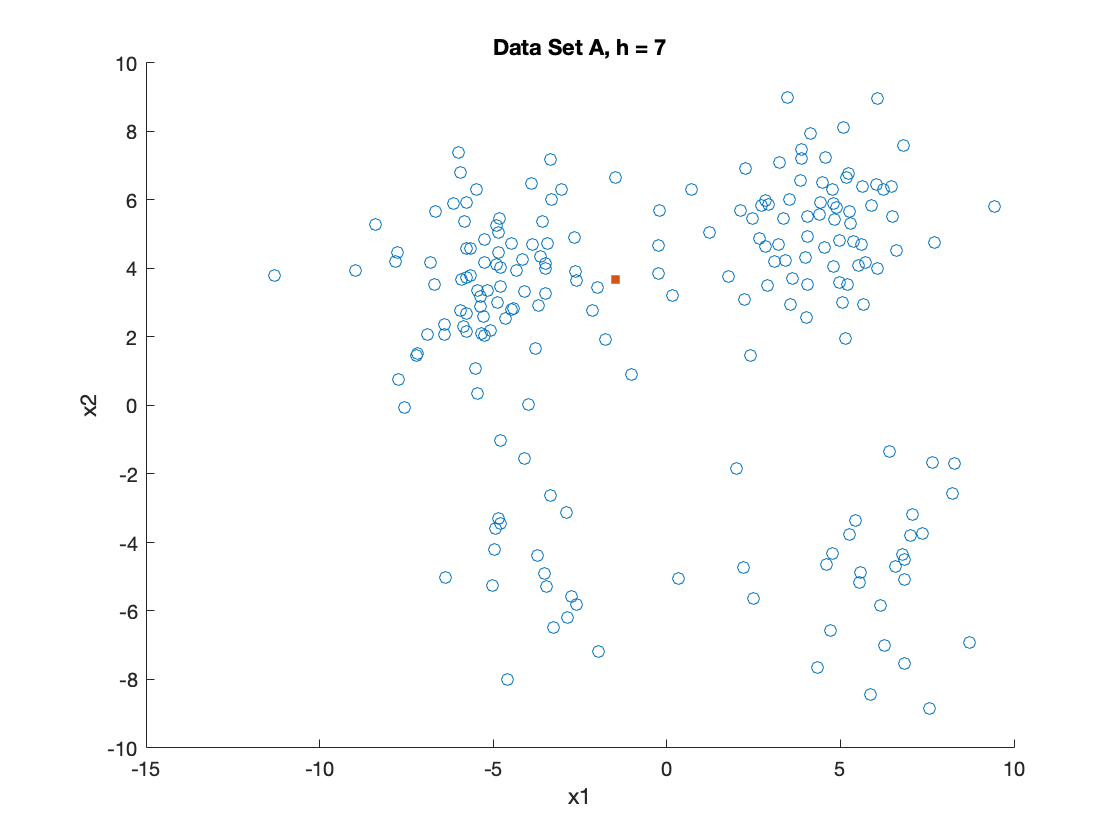

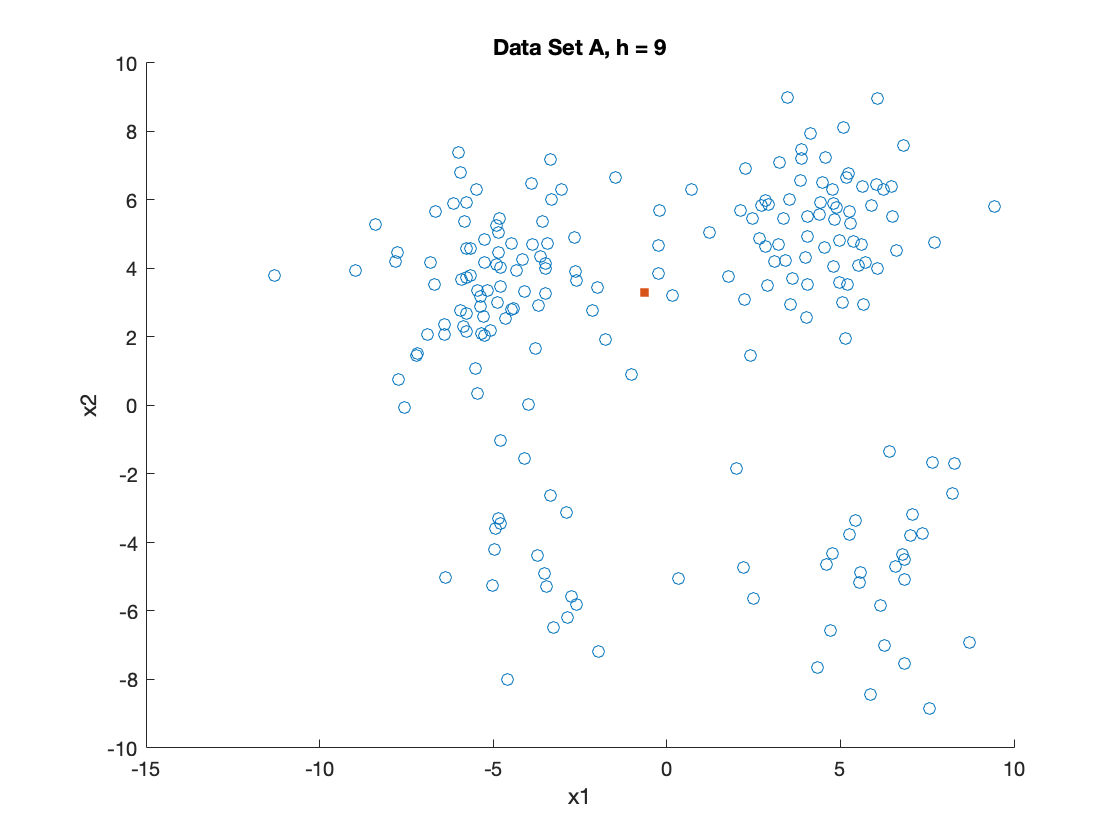

%A
cnt = 1;
for h = [0.5, 1:2:9]
    %train
    [mu_ms_q3, z_ms_q3] = ms(dataA_X, h, inf);
    %plot
    num_component = size(mu_ms_q3, 2);
    figure(cnt);
    for i = 1:num_component
        temp = dataA_X(:, z_ms_q3==i);
        scatter(temp(1,:), temp(2,:));
        hold on
        scatter(mu_ms_q3(1,i), mu_ms_q3(2,i), 30, "filled", "s");
    end
    hold off
    xlabel("x1");
    ylabel("x2");
    title("Data Set A, h = "+h);
    cnt = cnt+1;
end

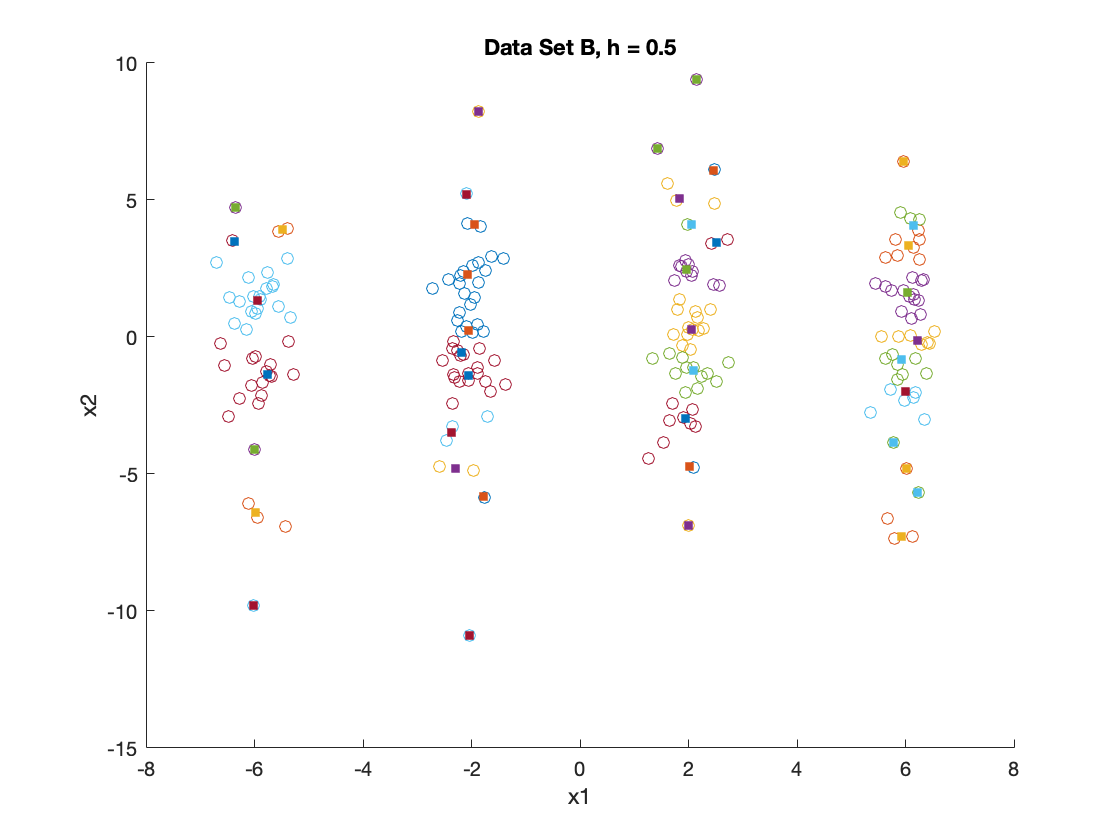

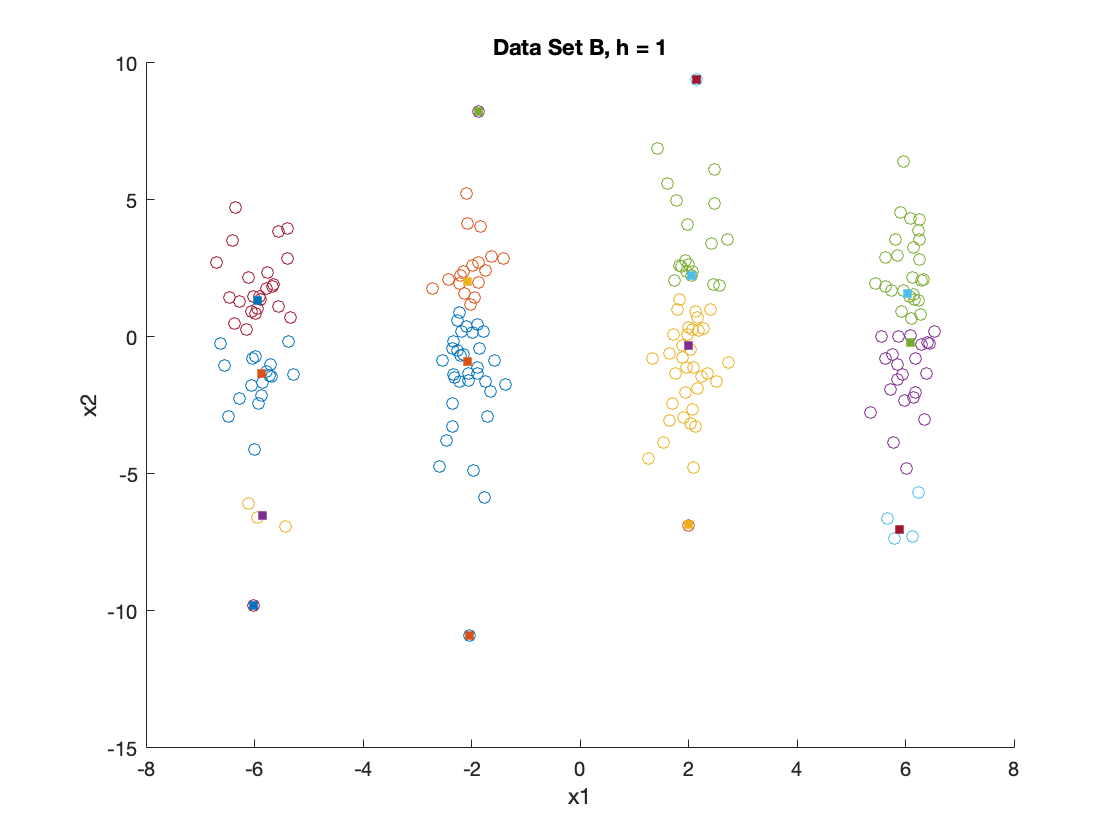

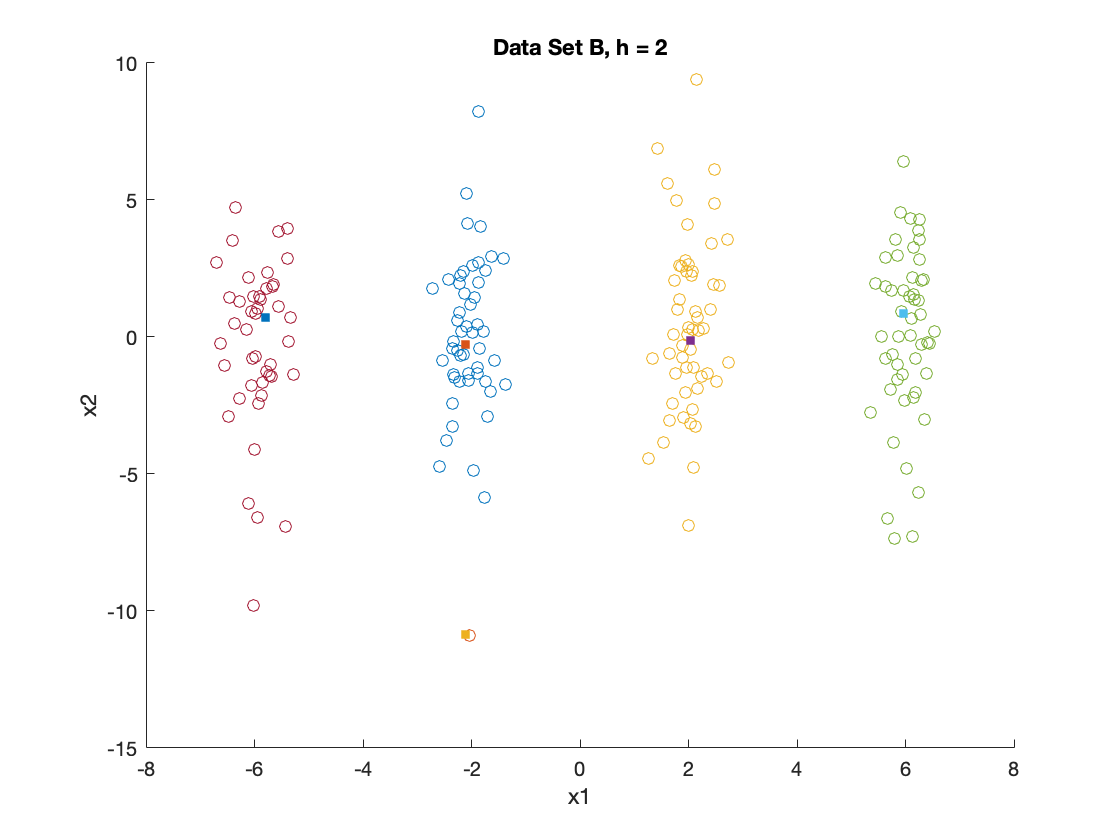

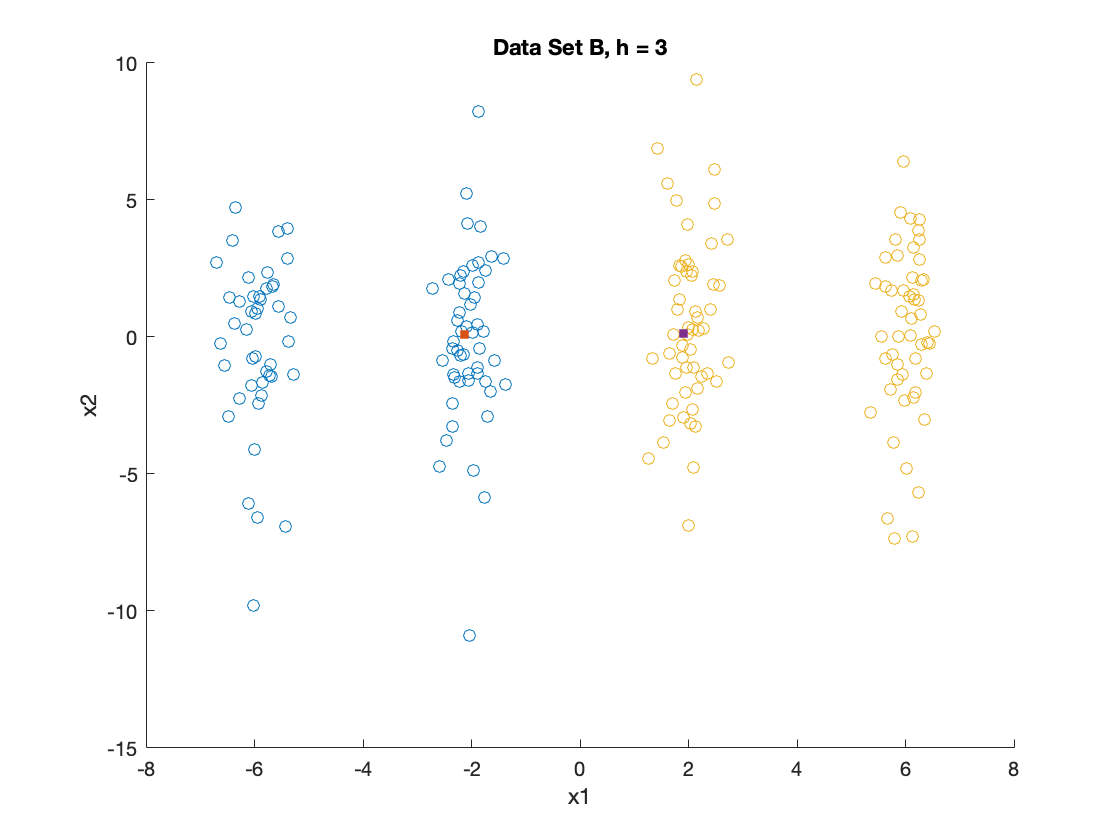

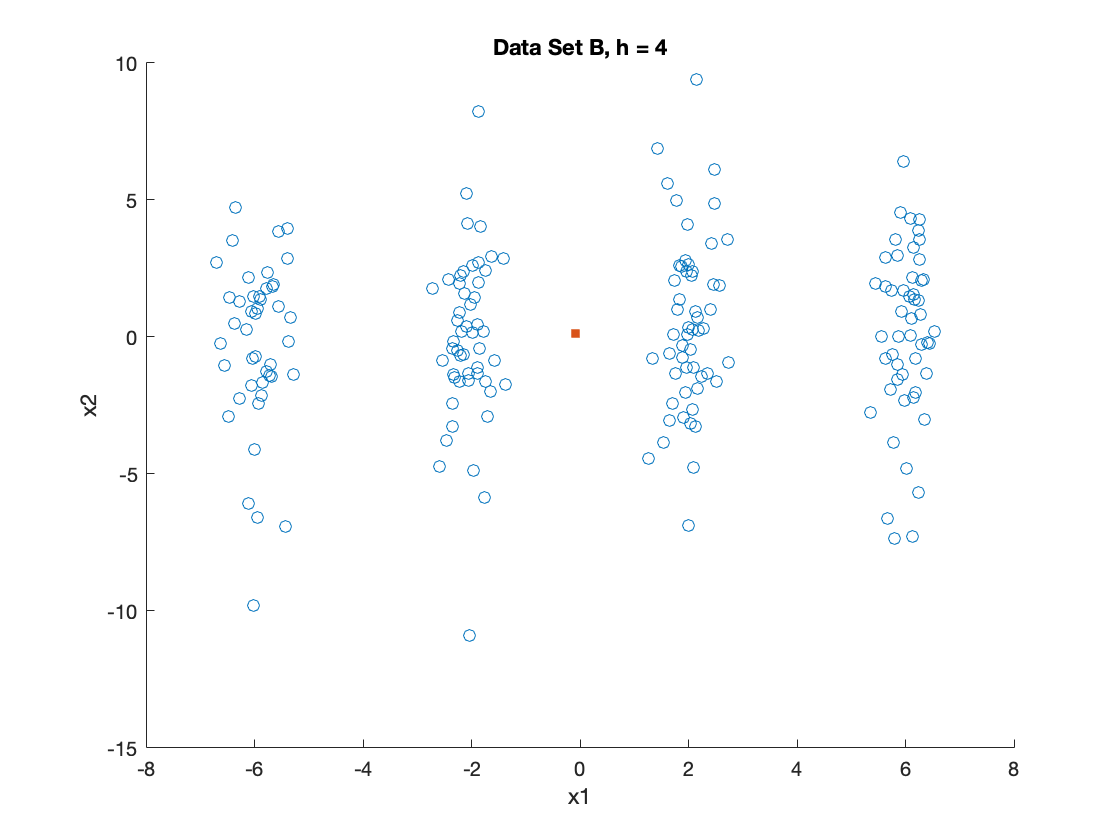

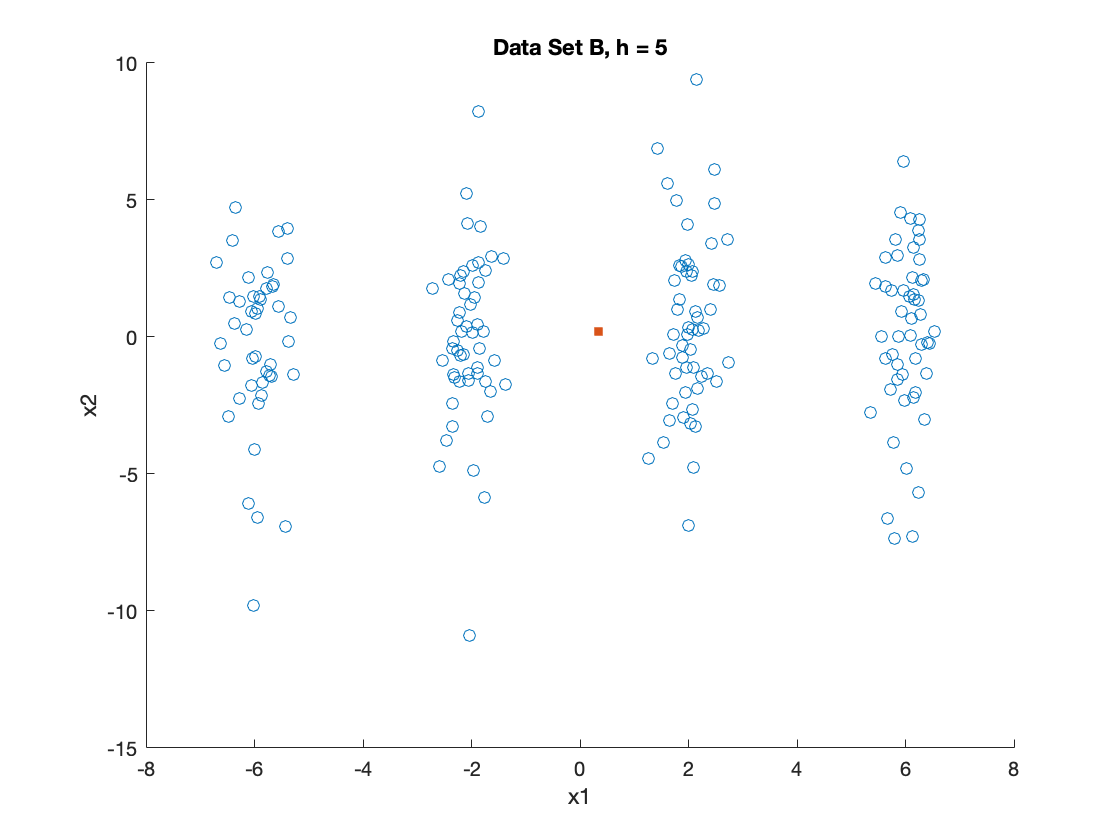


%B
cnt = 1;
for h = [0.5, 1:5]
    %train
    [mu_ms_q3, z_ms_q3] = ms(dataB_X, h, inf);
    %plot
    num_component = size(mu_ms_q3, 2);
    figure(cnt);
    for i = 1:num_component
        temp = dataB_X(:, z_ms_q3==i);
        scatter(temp(1,:), temp(2,:));
        hold on
        scatter(mu_ms_q3(1,i), mu_ms_q3(2,i), 30, "filled", "s");
    end
    hold off
    xlabel("x1");
    ylabel("x2");
    title("Data Set B, h = "+h);
    cnt = cnt+1;
end

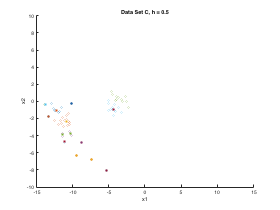

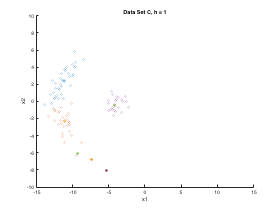

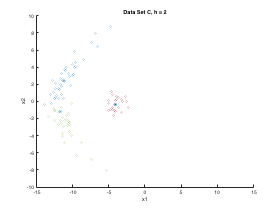

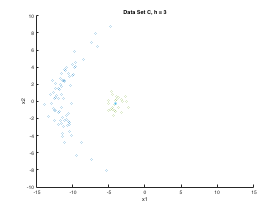

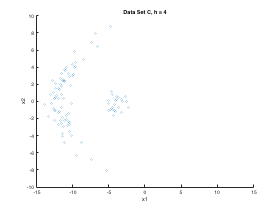

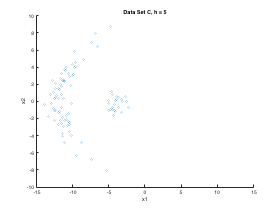

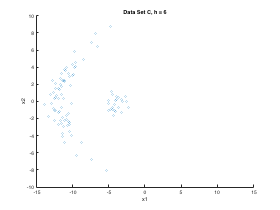

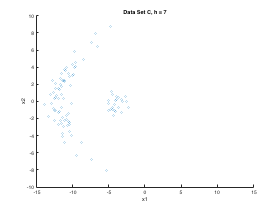


%C
cnt = 1;
for h = [0.5, 1:5]
    %train
    [mu_ms_q3, z_ms_q3] = ms(dataC_X, h, inf);
    %plot
    num_component = size(mu_ms_q3, 2);
    figure(cnt);
    for i = 1:num_component
        temp = dataC_X(:, z_ms_q3==i);
        scatter(temp(1,:), temp(2,:));
        hold on
        scatter(mu_ms_q3(1,i), mu_ms_q3(2,i), 30, "filled", "s");
    end
    hold off
    xlabel("x1");
    ylabel("x2");
    title("Data Set C, h = "+h);
    cnt = cnt+1;
end